%Inductor value, L:
L=49e-6;

%Capacitor Value, C:
C=940e-6; ...470e-6 + 470e-6 = 940e-6 (2 Capacitor)

%Internal resistance of capacitor, Rc:
Rc=0.1;  ...ESR of the capacitor is in parallel looking from the output.

%Maximum load(20% Maximum Power), R: 
R=5; 




%%Calcualtion Start
%1.0 Resonant Frequency, w_res
w_res = 1 / sqrt(L * C);
fprintf("Resonant Frequency, w_res: %.4f",w_res);

Resonant Frequency, w_res: 4659.4862


%1.1 CrossOver Frequency, w_c
w_c = 4 * w_res;
fprintf("CrossOver Frequency, w_c: %.4f ",w_c);

CrossOver Frequency, w_c: 18637.9449 

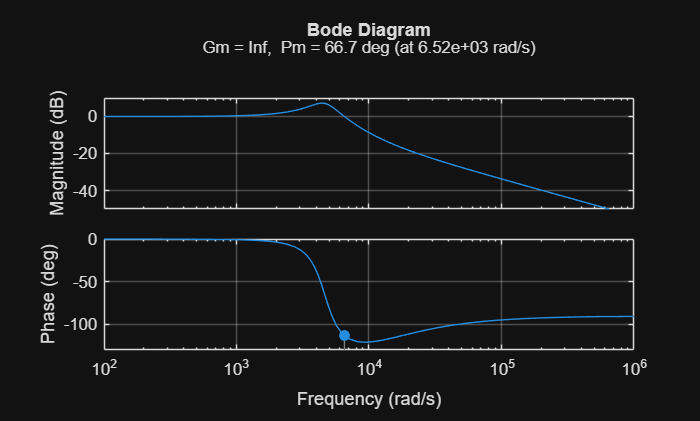



%----------------------------------------------------------------------------------

%2.0 Transfer Function of Gf(s) :
num_Gf = [Rc*C, 1];
den_Gf = [L*C, (L/R)+C*Rc, 1];

Gf = tf(num_Gf, den_Gf);
%2.1 Bode Plot of Gf:
figure;
margin(Gf); 
grid on;

[mag_Gf, phase_Gf]=bode(Gf,w_c);

%Display Magnitude & Phase
Gf


Gf =
 
           9.4e-05 s + 1
  -------------------------------
  4.606e-08 s^2 + 0.0001038 s + 1
 
Continuous-time transfer function.


fprintf("Magnitude at w_c                 : %.4f",mag_Gf);

Magnitude at w_c                 : 0.1334

fprintf("absolute Magnitude in dB at w_c  : %.4f",(20*log10(mag_Gf)));

absolute Magnitude in dB at w_c  : -17.4982

fprintf("Phase at w_c                     : %.4f",phase_Gf);

Phase at w_c                     : -112.3680


%----------------------------------------------------------------------------------

%3.0 Calculate Boost, B:

%Phase Margin,PM
PM = 60;

B = PM - 180 + 90 - phase_Gf;
fprintf("Phase Boost, B = %.4f",B);

Phase Boost, B = 82.3680


%----------------------------------------------------------------------------------

%4.0 Calculate k-factor, k :
k = (tand((B/4)+45))^2;
fprintf("k factor, k = %.4f", k);

k factor, k = 4.8562


%----------------------------------------------------------------------------------

%5.0 Calculate K_misc :
V_opamp = 3; %Can change to desired op amp voltage(no more than 5V)
V_out  = 8;  %Fixed Can't be change

a = V_opamp / V_out; % R2/(R2+R1) = a

d = 0.45; % Maximum Duty Cycle
V_a = 3.5; % From Datasheet(SG3524A) Maximum Duty cycle
V_b = 1;  % From Datasheet(SG3524A) Zero Duty cycle

K_pwm = d /(V_a - V_b);

Vs0 = 39.7392; %Maximum Voltage (Can use Simulation??)
n = 1; % Turn Ratio of Main Transformer

K_misc = a * K_pwm * Vs0 * n;
fprintf("K_misc : %.4f", K_misc);

K_misc : 2.6824


%----------------------------------------------------------------------------------

%6.0 Gain of the Controller, G:

G = 1 / (K_misc * mag_Gf);
fprintf("Gain, G : %.4f",G);

Gain, G : 2.7950

%----------------------------------------------------------------------------------
%7.0 WorkOut Components
fprintf("For Z1: ");

For Z1: 

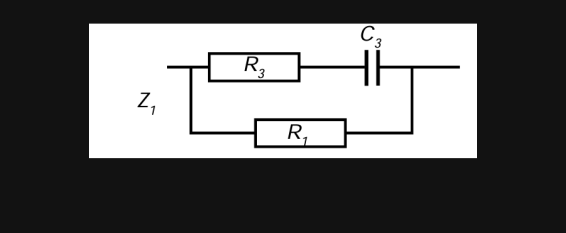

img_Z1 = imread("Z1.png"); % Show image
figure;
imshow(img_Z1);


R1 = 10e3; %Set R1 to 1k Ohm 
R3 = R1 / (k-1);
C3 = 1 / (R3*w_c*sqrt(k));

fprintf("R1 : %.4f", R1);

R1 : 10000.0000

fprintf("R3 : %.4f", R3);

R3 : 2593.2501

fprintf("C3 : %.4e", C3);

C3 : 9.3888e-09


fprintf("For Z2: ");

For Z2: 

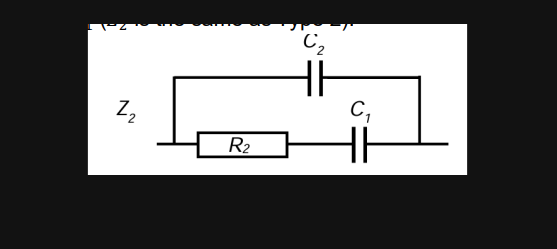

img_Z2 = imread("Z2.png "); % Show image
figure;
imshow(img_Z2);


C2 = 1 / (R1*w_c*G);
C1 = C2 * (k-1);
R2 = sqrt(k) / (w_c*C1);
fprintf("C1 : %.4e", C1);

C1 : 7.4024e-09

fprintf("C2 : %.4e", C2);

C2 : 1.9196e-09

fprintf("R2 : %.4e", R2);

R2 : 1.5973e+04


%Check Gain, G_check :

A = 1 / ((C1+C2)*R1);

A_check = G * w_c / k

A_check = 1.0727e+04

G_check = (A*k) / w_c;

fprintf("A : %.4f", A);

A : 10727.3102

fprintf("G_check : %.4f", G_check);

G_check : 2.7950


%----------------------------------------------------------------------------------

% 8.0 Find G controller, Gc:

s = tf('s');

w_z = w_c / sqrt(k) % w_z = w_z1 = w_z2

w_z = 8.4577e+03

w_p = w_c * sqrt(k) % w_p = w_p1 = w_p2

w_p = 4.1072e+04


Num_Gc = A * (1 + (s/w_z))^2;
Den_Gc = s * (1 + (s/w_p))^2;

Gc = Num_Gc / Den_Gc;

Gc


Gc =
 
    1.81e13 s^2 + 3.061e17 s + 1.294e21
  ----------------------------------------
  7.153e07 s^3 + 5.876e12 s^2 + 1.207e17 s
 
Continuous-time transfer function.


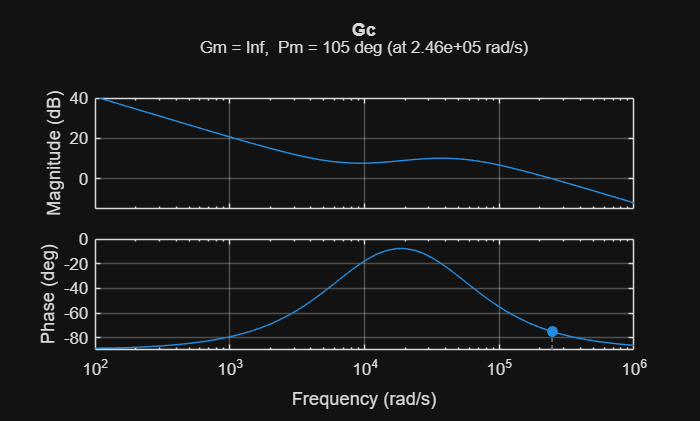

figure;
margin(Gc); 
grid on;
title("Gc");


%----------------------------------------------------------------------------------

% 9.0 Find G loop, G_loop:

G_loop = Gc * Gf * K_misc


G_loop =
 
         4.563e09 s^3 + 1.257e14 s^2 + 1.147e18 s + 3.472e21
  ------------------------------------------------------------------
  3.295 s^5 + 2.781e05 s^4 + 6.239e09 s^3 + 1.84e13 s^2 + 1.207e17 s
 
Continuous-time transfer function.



disp("G_loop tf: ")

G_loop tf: 


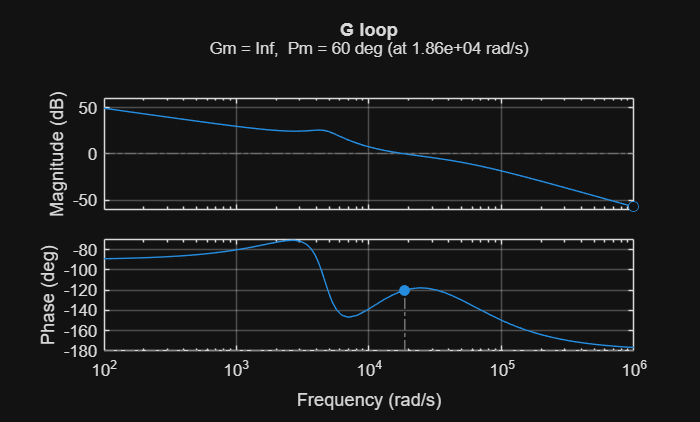

figure;
margin(G_loop); 
grid on;
title("G loop");

[mag_G_loop, phase_G_loop]=bode(G_loop,100);
fprintf("Magnitude at 100Hz                 : %.4f",mag_G_loop);

Magnitude at 100Hz                 : 287.9173

fprintf("absolute Magnitude in dB at 100Hz  : %.4f",(20*log10(mag_G_loop)));

absolute Magnitude in dB at 100Hz  : 49.1854


%----------------------------------------------------------------------------------

% 10.0 Find G closed loop, G_cloop;

G_cloop = G_loop / (1+G_loop)


G_cloop =
 
                1.503e10 s^8 + 1.683e15 s^7 + 6.721e19 s^6 + 1.199e24 s^5 + 1.099e28 s^4 + 5.795e31 s^3 + 2.024e35 s^2 + 4.19e38 s
  ----------------------------------------------------------------------------------------------------------------------------------------------
  10.86 s^10 + 1.832e06 s^9 + 1.335e11 s^8 + 5.274e15 s^7 + 1.172e20 s^6 + 1.496e24 s^5 + 1.283e28 s^4 + 6.239e31 s^3 + 2.169e35 s^2 + 4.19e38 s
 
Continuous-time transfer function.



disp("G_close_loop tf: ")

G_close_loop tf: 


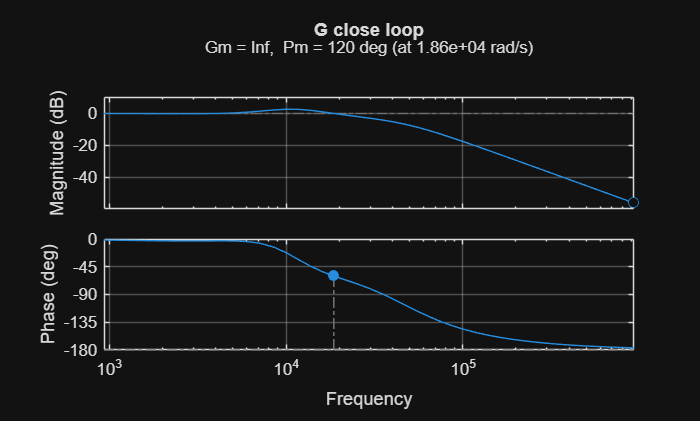

figure;
margin(G_cloop); 
grid on;
title("G close loop");

%%Calcualtion End

